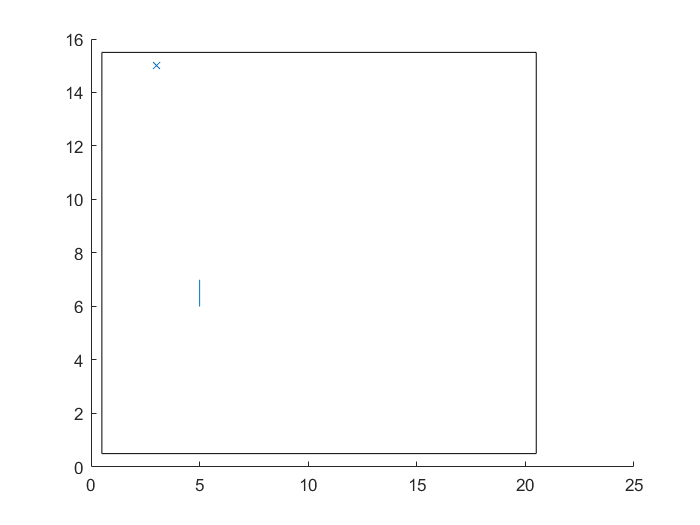

sysParams.BOARD_WIDTH = 20;
sysParams.BOARD_HEIGHT = 15;

snakePos = [[randperm(sysParams.BOARD_WIDTH, 1); randperm(sysParams.BOARD_HEIGHT, 1)] zeros(2,2)];
dir = 0; % 0 right, 1 up, 2 left, 3 down
length = 3;
fruitPos = [randperm(sysParams.BOARD_WIDTH, 1);randperm(sysParams.BOARD_HEIGHT, 1)];
round = 0;
score = 0;
board = zeros(sysParams.BOARD_HEIGHT, sysParams.BOARD_WIDTH);
gameOn = 1;

while gameOn
    round = round + 1;
    board = updateState(board, snakePos, fruitPos);
    % choose move
    dir = randperm(4,1)-1;
    snakePos = moveSnake(snakePos, dir);
    length = checkFruit(snakePos, fruitPos);
    if length > size(snakePos, 2)
        snakePos = [snakePos [0;0]];
    end
    gameOn = checkBoardExit(sysParams, snakePos) && checkCollision(snakePos);
    
    % Draw Board
    figure(1);
    clf;
    line([.5;.5+sysParams.BOARD_WIDTH;.5+sysParams.BOARD_WIDTH;.5; .5], [.5;.5;.5+sysParams.BOARD_HEIGHT;.5+sysParams.BOARD_HEIGHT; .5], 'color', 'black');
    hold on;
    line(snakePos(1,snakePos(1,:) ~= 0), snakePos(2,snakePos(1,:) ~= 0));
    plot(fruitPos(1,1), fruitPos(2,1), 'x');
    hold off;
    drawnow;
end

function board = updateState(board, snakePos, fruitPos)
    board = zeros(size(board));
    board(fruitPos(2,1), fruitPos(1,1)) = 2;
    for i=1:size(snakePos,2)
        if (sum(snakePos(:,i)) ~= 0)
            board(snakePos(2,i), snakePos(1,i)) = 1;
        end
    end
end

function snakePos = moveSnake(snakePos, dir)
    for i=size(snakePos, 2):-1:2
        snakePos(:, i) = snakePos(:, i-1);
    end
    switch dir
        case 0
            snakePos(:,1) = snakePos(:,1) + [1;0];
        case 1
            snakePos(:,1) = snakePos(:,1) + [0;1];
        case 2
            snakePos(:,1) = snakePos(:,1) + [-1;0];
        case 3
            snakePos(:,1) = snakePos(:,1) + [0;-1];
        otherwise
            disp("Invalid input");
    end
end

function length = checkFruit(snakePos, fruitPos)
    length = size(snakePos, 2);
    if snakePos(:,1) == fruitPos
        length = length + 1;
    end
end

function gameOn = checkBoardExit(sysParams, snakePos)
    gameOn = 1;
    if snakePos(1,1) < 1 || snakePos(1,1) > sysParams.BOARD_WIDTH
        gameOn = 0;
    elseif snakePos(2,1) < 1 || snakePos(2,1) > sysParams.BOARD_HEIGHT
        gameOn = 0;
    end
end

function gameOn = checkCollision(snakePos) 
    gameOn = 1;
    for i=2:size(snakePos, 2)
        if snakePos(:, i) == snakePos(:,1)
            gameOn = 0;
            break;
        end
    end
end